# Human Activity Clustering

This is an unsupervised learning example.

Human activity sensor data contains observations derived from sensor measurements taken from smartphones worn by people while doing different activities (walking, laying, sitting, etc.). [Watch the experiment video](https://www.youtube.com/watch?v=XOEN9W05_4A).

The goal of this analysis is to identify clusters of similar activities and what they may represent, in the absence of labels.  **In this unsupervised learning example, we do not know in advance what type of activity each observation corresponds to. **

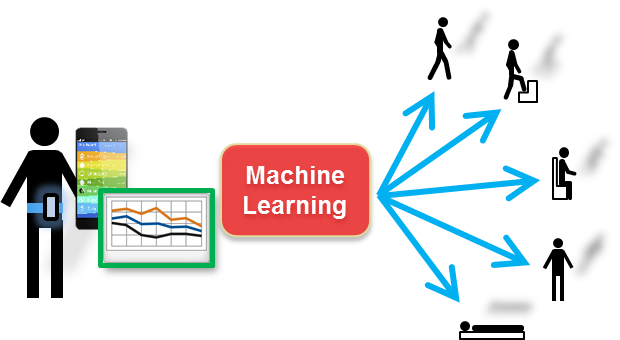

**Housekeeping**

Clear the workspace.

clear;

Double check if you are in the right directory. If yes, add the folder and subfolders to the path.

% Run this to check
if isfolder('Additional Files')
    addpath(genpath(pwd))
    disp('You are in the correct directory. Please continue.')
else  
    disp('Please navigate to the proper Directory')
end

## Load data

We will load in the `rawSensorData`, which contains of 6 variables, each representing measurments from a different sensor (x, y, z components of an accelerometer and x, y, z components of a gyroscope). The `trainActivity` variable contains the actual labels which will only be used to evaluate the model.

We can import the data with the *Import Data* tool which can be found in the *HOME* tab.

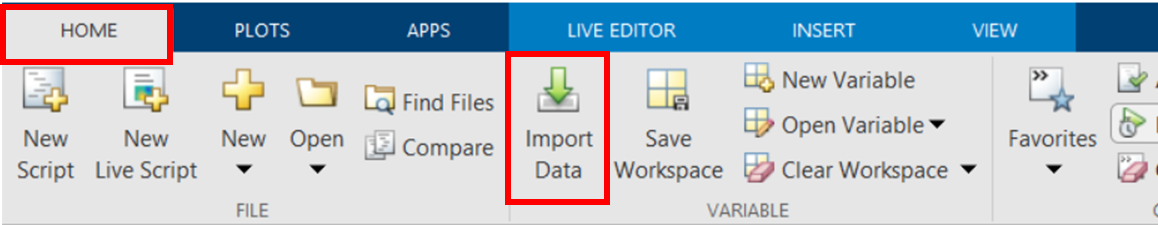

In there, choose the ***Additional Files*** folder (double click) and the ***rawSensorData_train.mat*** file (click on 'Open' or double click). All variables are selected by default, press ***Finish***.

Note: In the desktop MATLAB®, you can generate the code for this activity by ticking the box at the bottom (Generate MATLAB code). In MATLAB Online, you can see the code in the *Command Window*.

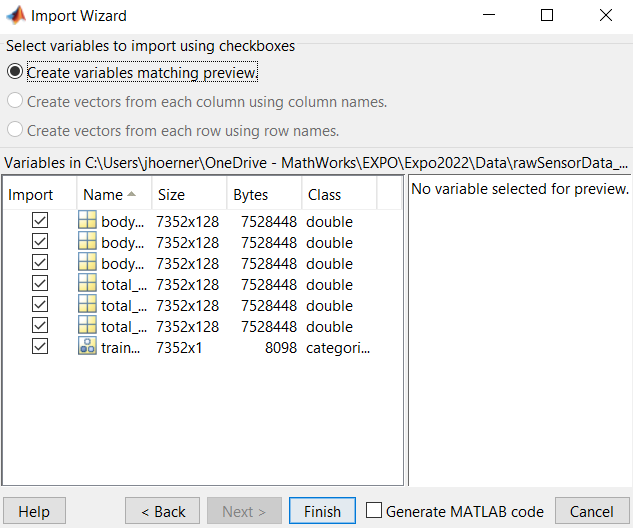

You should then see the 7 variables in the workspace.

Each row represents one observation (128 data points = 128 columns). We will attempt to find clusters by grouping "similar" rows. This will help us to make sense of the data set in the absence of output data (labels).

## Preprocess data

Because of the large amount of individual data points, it is difficult to group the activities. For this reason, we will reduce the number of data points in each observation by calculating the mean value and the standard deviation. This can be seen a dimensionality reduction.

First, let's calculate the [mean](https://uk.mathworks.com/help/matlab/ref/mean.html) and [standard deviation](https://uk.mathworks.com/help/matlab/ref/std.html) and put them into one single array.

accX_mean = mean(total_acc_x, 2);
accY_mean = mean(total_acc_y, 2);
accZ_mean = mean(total_acc_z, 2);
gyroX_mean = mean(body_gyro_x, 2);
gyroY_mean = mean(body_gyro_y, 2);
gyroZ_mean = mean(body_gyro_z, 2);

accX_std = std(total_acc_x, [], 2);
accY_std = std(total_acc_y, [], 2);
accZ_std = std(total_acc_z, [], 2);
gyroX_std = std(body_gyro_x, [], 2);
gyroY_std = std(body_gyro_y, [], 2);
gyroZ_std = std(body_gyro_z, [], 2);

% combine in one single array
ActivityDataTrain = [accX_mean accY_mean accZ_mean accX_std accY_std accZ_std ...
    gyroX_mean gyroY_mean gyroZ_mean gyroX_std gyroY_std gyroZ_std];

% clear variables (to keep workspace clean)
clear accX_mean accY_mean accZ_mean accX_std accY_std accZ_std gyroX_mean gyroY_mean gyroZ_mean gyroX_std gyroY_std gyroZ_std

## K-Means clustering

[Open kmeans documentation](matlab: doc kmeans)

K-Means clustering is a method of partitioning your data set into K mutually exclusive clusters or groups.  It treats each observation in your data as an object having a location in space and finds a partition in which objects within each cluster are as close to each other as possible, and as far from objects in other clusters as possible.  K-Means uses an iterative algorithm that minimizes the sum of distances from each object to its cluster centroid, over all clusters. 

**K-Means:**

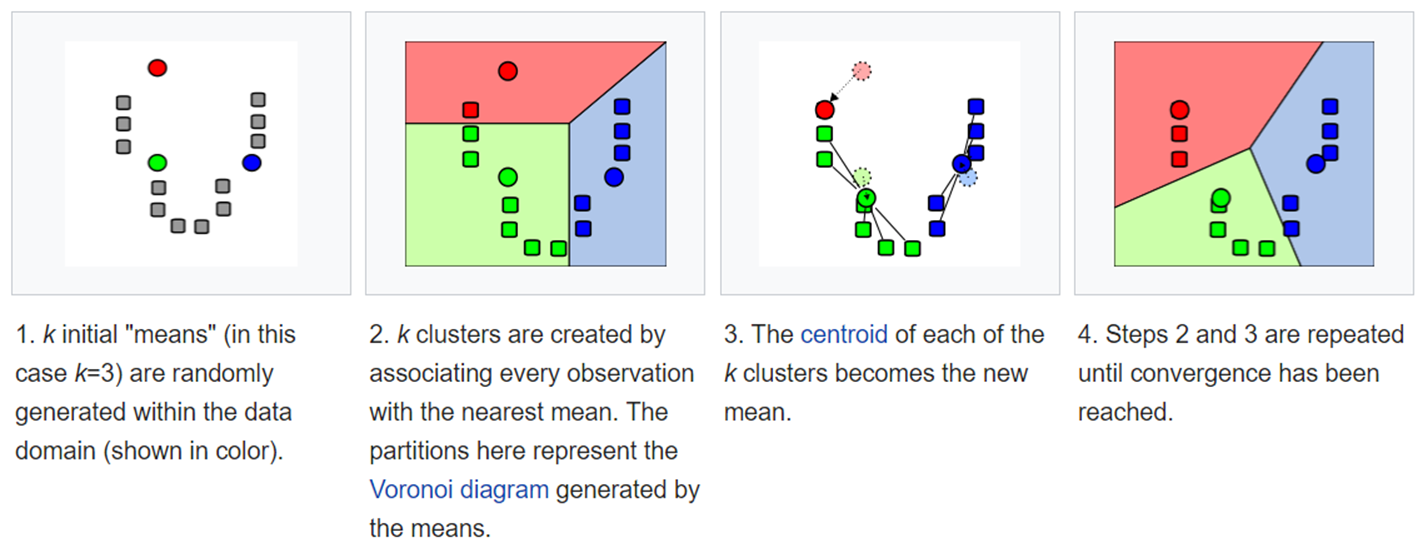

[Source: Wikipedia](https://en.wikipedia.org/wiki/K-means_clustering)

You can use a *Live Task* to cluster the data. This can be found in the *LIVE EDITOR* tab under *Task*. Please select *Cluster Data*.

Choose the array `ActivityDataTrain` as input data.

You can specify the number of clusters. Assuming that we do not have the labels, we can either choose the actual number of classes (6 classes: standing, sitting, laying, walking, walking downstairs, walking upstairs) or we can start with a smaller number to see how it performs.

You can play around with the number of classes and choose for example 2 classes (stationary, moving) or 3 classes (stationary, laying, moving).

Note: You can find the optimal number of clusters by changing the *Selection method* to *Optimal* and specify the range of number of clusters and the *Evaluation criterion*.

rng('default') % controls the random seed so we get the same results everytime we run the clustering task

% Insert the live task here



## Evaluate the model

Since we have the actual labels of the activities we can double check if our model was correct.

Therefore, we'll get the indices for each cluster and display the activities for these indices.

Note: This code works for 3 clusters, you need to adjust if you have more or less clusters.

idx_cl1 = clusterIndices==1;
idx_cl2 = clusterIndices==2;
idx_cl3 = clusterIndices==3;

act_1 = trainActivity(idx_cl1, :);
act_2 = trainActivity(idx_cl2, :);
act_3 = trainActivity(idx_cl3, :);
summary(act_1); %cluster 1
summary(act_2); %cluster 2
summary(act_3); %cluster 3

As we can see, the model grouped most of the activities in the correct clusters.

## Summary and next steps

In this example we clustered our measurements acquired from a mobile phone into groups with similar characteristics. This technique can be useful to find patterns, but also to label data (if labels are not available).

We applied k-means clustering technique which gave relatively good results. You could also try other methods which are described [here](https://uk.mathworks.com/help/stats/cluster-analysis.html).

*Copyright 2022, The MathWorks, Inc.*